## Exercise 1

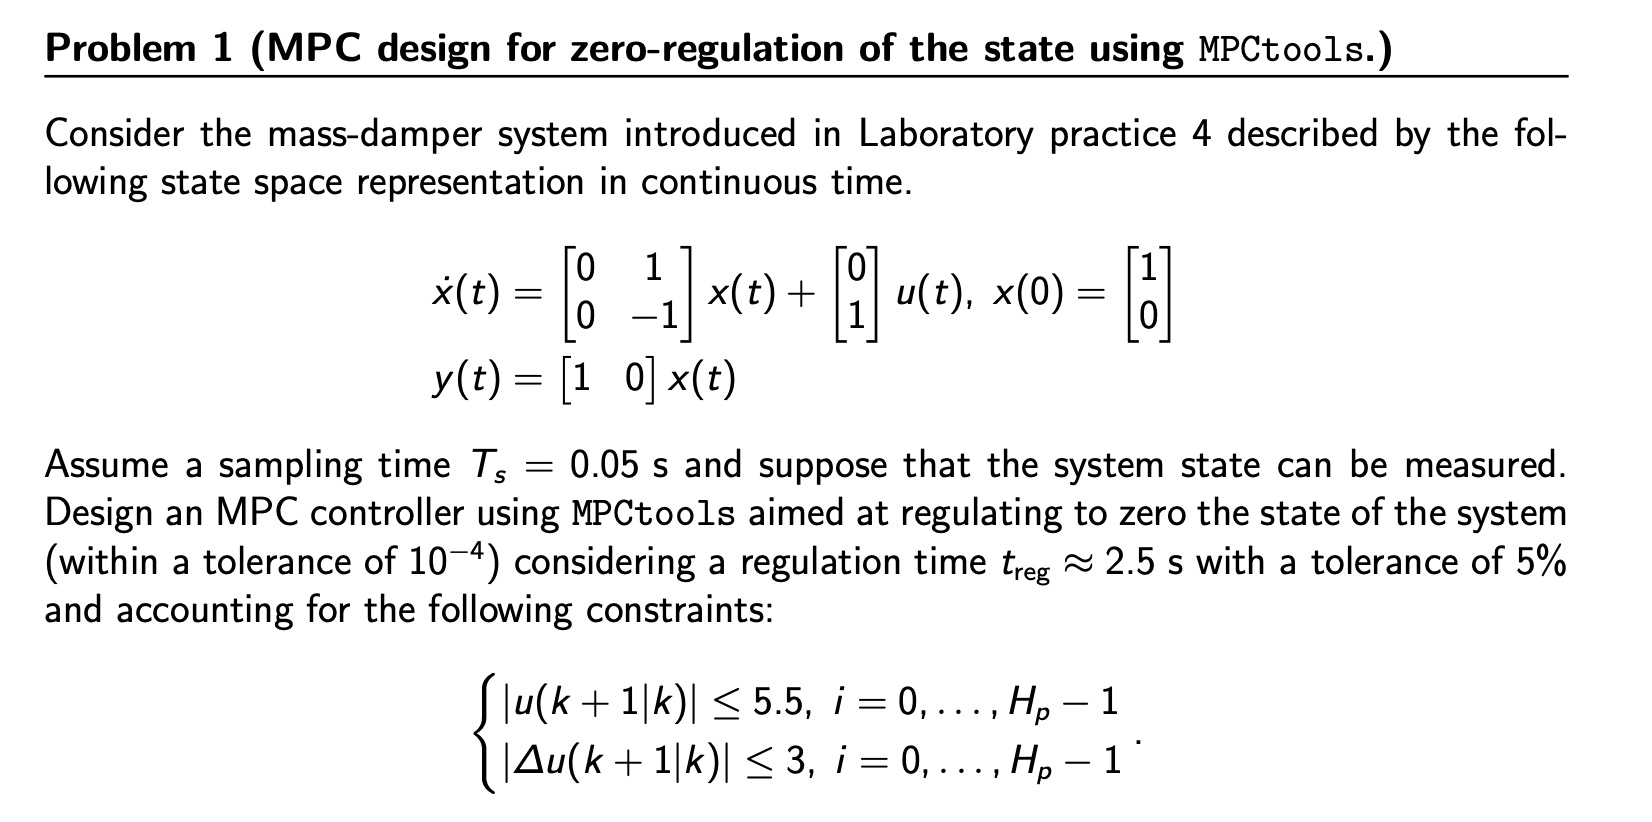

close all
clear
clc

addpath("MPCtools/");


A = [0 1; 0 -1];
B = [0;1];
C = [1 0];
x0 = [1;0];
Ts = 0.05;
D = 0;

sys = ss(A,B,C,D);
sys_x = ss(A,B,eye(2),0);

Ts = 0.05;

sys_dt = c2d(sys,Ts,'zoh');
Ad = sys_dt.a;
Bd = sys_dt.b;
Cd = sys_dt.c;
Dd = sys_dt.d;


#### Set design parameters for MPCtools

Cy = eye(2); % measured output -> all states measured -> we assume that the output measured is the state => C must be eye
Cz = eye(2); Dz = [0;0]; % controlled output -> 2 states because we are interested in state regulation 
Cc = Cz; Dc = Dz; % constrained output = controlled output
Q = diag([1,1]);
R = 1;
cmode = 0; % state feedback mode
h = Ts;
z_max = [inf inf]; % output constraints -> are the state constraints since Cz = eye
z_min = [-inf -inf]; 
u_max = [5.5]; % input constraints
u_min = [-5.5]; 
du_max = [3]; % rate constraints
du_min = [-3]; 
Hp = 55; % prediction horizon
Hu = 55; % control horizon
Hw = 1; % first penalty sample 
z_blk = 1; % no blocking
u_blk = 1; % no blocking

#### Compute MPC controller

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Unrecognized function or variable 'MPCInit'.

#### Simulation

t_sim = 5;
t_reg = 2.5;
out = sim('sim_mpc.slx'); 
figure
subplot(221)
plot(out.x.time, out.x.data(:,1))
ylabel("x_1(t)")
subplot(222)
plot(out.x.time, out.x.data(:,2))
ylabel("x_2(t)")
subplot(223)
plot(out.x.time, sqrt(out.x.data(:,1).^2+out.x.data(:,2).^2))
yline(1e-4,':r','LineWidth',1.5)
yline(-1e-4,':r','LineWidth',1.5)
xline(t_reg*0.95,'LineWidth',1.5)
xline(t_reg*1.05,'LineWidth',1.5)
ylabel("norm")
subplot(224)
plot(out.u.time, out.u.data)
ylabel("control input")

### Tuning

Q(1,1) = 3e3;
Q(2,2) = 1;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

clear out

out = sim('sim_mpc.slx'); 
figure
subplot(221)
plot(out.x.time, out.x.data(:,1))
ylabel("x_1(t)")
subplot(222)
plot(out.x.time, out.x.data(:,2))
ylabel("x_2(t)")
subplot(223)
plot(out.x.time, sqrt(out.x.data(:,1).^2+out.x.data(:,2).^2))
yline(1e-4,':r','LineWidth',1.5)
yline(-1e-4,':r','LineWidth',1.5)
xline(t_reg*0.95,'LineWidth',1.5)
xline(t_reg*1.05,'LineWidth',1.5)
ylabel("norm")
subplot(224)
plot(out.u.time, out.u.data)
ylabel("control input")

Now we work on Hp and Hc 

We can reduce Hp = 50 but we can't go further decreasing 

Then we can decrease Hu and see until response is still good

% Hp = 50;
Hu = 20;

md = MPCInit(Ad,Bd,Cy,Cz,Dz,Cc,Dc,Hp,Hw,z_blk, Hu,u_blk, ...
    du_max,du_min,u_max,u_min,z_max,z_min,Q,R,[],[],h, cmode, ...
    'qp_as');

Setting up matrices...
Preparing matrix setup...
Building prediction matrices...
Post-creation matrix operations...



clear out

out = sim('sim_mpc.slx'); 

Update start, t=0.00
Update start, t=0.05
Update start, t=0.10
Update start, t=0.15
Update start, t=0.20
Update start, t=0.25
Update start, t=0.30
Update start, t=0.35
Update start, t=0.40
Update start, t=0.45
Update start, t=0.50
Update start, t=0.55
Update start, t=0.60
Update start, t=0.65
Update start, t=0.70
Update start, t=0.75
Update start, t=0.80
Update start, t=0.85
Update start, t=0.90
Update start, t=0.95
Update start, t=1.00
Update start, t=1.05
Update start, t=1.10
Update start, t=1.15
Update start, t=1.20
Update start, t=1.25
Update start, t=1.30
Update start, t=1.35
Update start, t=1.40
Update start, t=1.45
Update start, t=1.50
Update start, t=1.55
Update start, t=1.60
Update start, t=1.65
Update start, t=1.70
Update start, t=1.75
Update start, t=1.80
Update start, t=1.85
Update start, t=1.90
Update start, t=1.95
Update start, t=2.00
Update start, t=2.05
Update start, t=2.10
Update start, t=2.15
Update start, t=2.20
Update start, t=2.25
Update start, t=2.30
Update start,

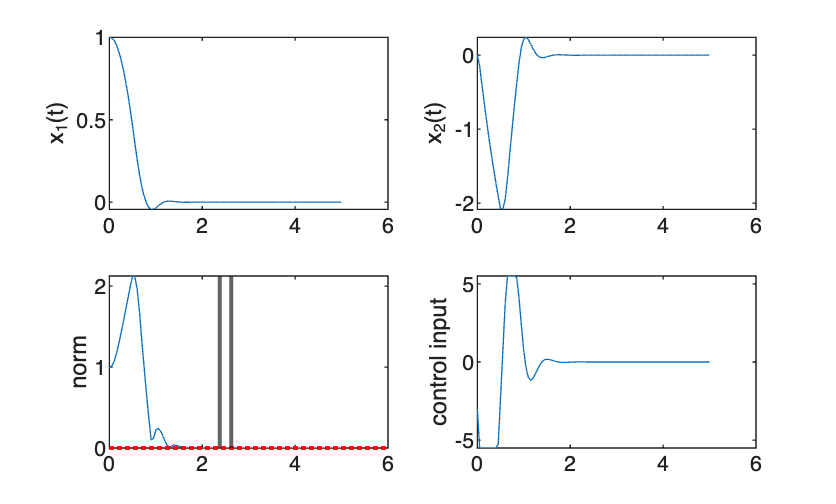

figure
subplot(221)
plot(out.x.time, out.x.data(:,1))
ylabel("x_1(t)")
subplot(222)
plot(out.x.time, out.x.data(:,2))
ylabel("x_2(t)")
subplot(223)
plot(out.x.time, sqrt(out.x.data(:,1).^2+out.x.data(:,2).^2))
yline(1e-4,':r','LineWidth',1.5)
xline(t_reg*0.95,'LineWidth',1.5)
xline(t_reg*1.05,'LineWidth',1.5)
ylabel("norm")
subplot(224)
plot(out.u.time, out.u.data)
ylabel("control input")

## Exercise 2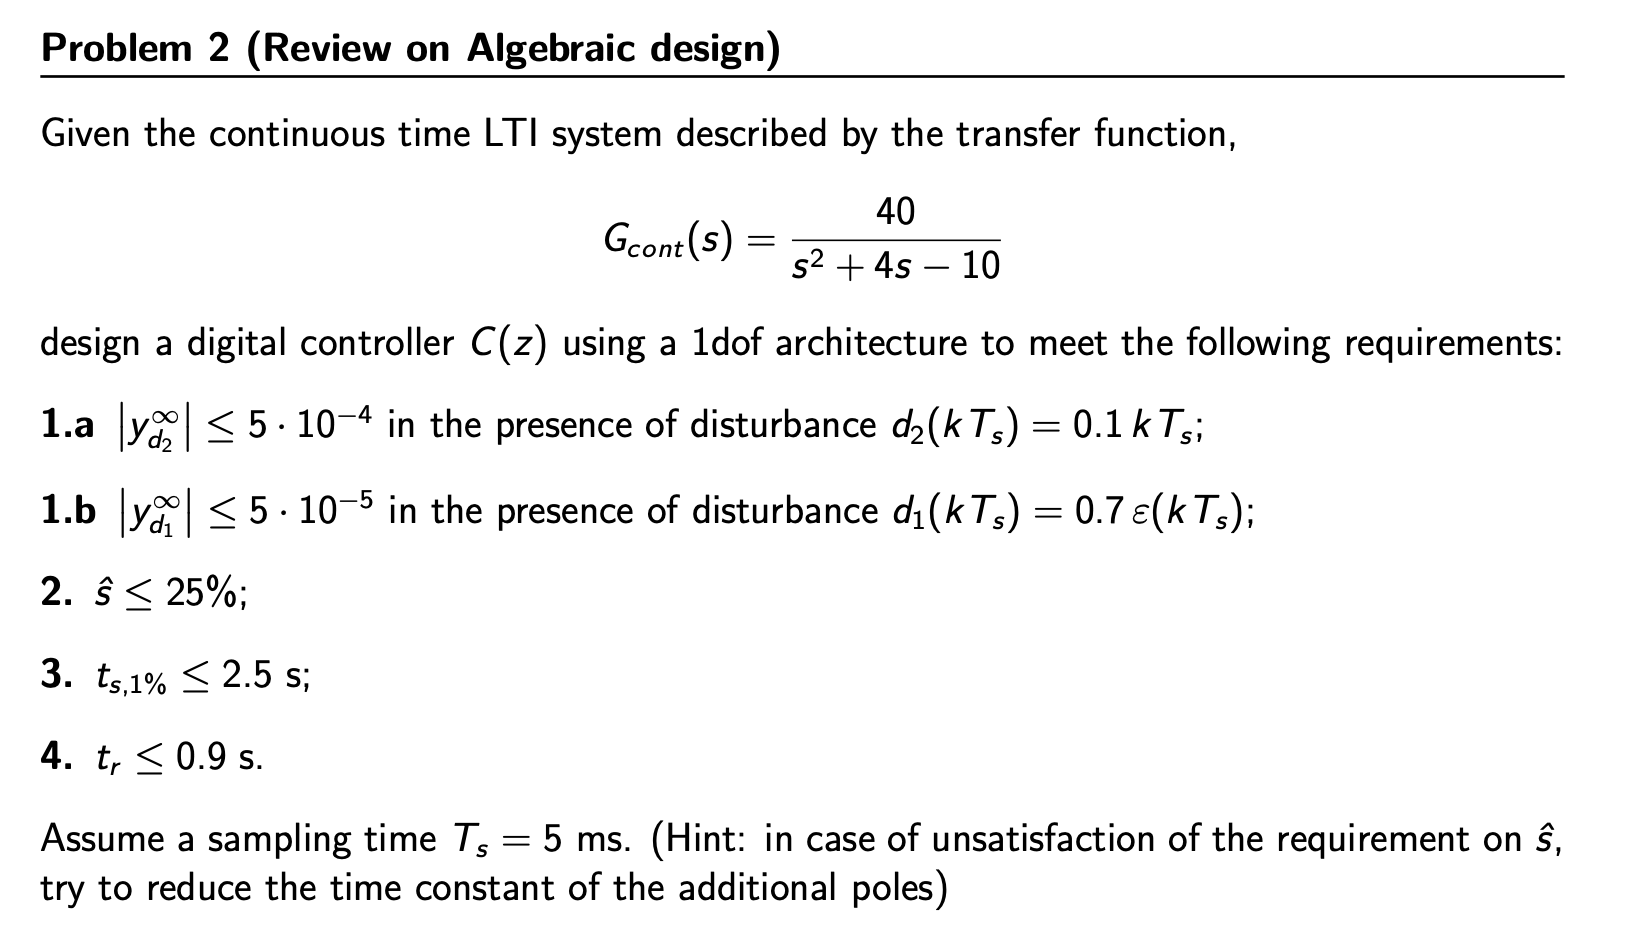

close all
clear
clc
Ts = 5e-3;
s = tf('s');
z = tf('z', Ts);


G_cont = 40/(s^2+4*s-10);

G = c2d(G_cont, Ts, 'zoh');
G = zpk(G)


G =
 
  0.00049669 (z+0.9934)
  ---------------------
  (z-1.009) (z-0.9717)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.


[zG, pG, kG] = zpkdata(G, 'v')

zG = -0.9934

pG =     1.0087
    0.9717


kG = 4.9669e-04



A = conv([1 -pG(1)], [1 -pG(2)]);
B = kG*[1 -zG];

#### SS requirements

l1 = 0;
l2 = 1;
l = 1; 
n_add = 1;

#### Transient response

s_hat = 0.25;
t_s = 2.5;
zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2); 
wn = 4.6/(zeta*t_s);  

% figure
% pzmap(G, 'r')
% hold on
% zgrid(zeta,wn, Ts)
% axis('equal')

From the figure we see that we can only cancel pG(2)

A_plus = [1 -pG(2)];
A_minus = [1 -pG(1)];
B_plus = 1;
B_minus = B;

% degrees

deg_A = 2;
deg_A_minus = 1;
deg_A_plus = 1;
deg_B_plus = 0;
deg_B_minus = 1;

deg_S1 = l + deg_A_minus - 1 + n_add

deg_S1 = 2

deg_R2 = deg_A - deg_B_plus + l1 - 1 + n_add

deg_R2 = 2

deg_Am = l + deg_A + deg_A_minus + l1 - deg_B_plus - 1 + n_add

deg_Am = 4

Since deg(Am) = 4 =>  we need 4 poles. we'll choose 2 complex conj poles and 2 real ones

p1c = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT
p2c = -zeta*wn - 1j*wn*sqrt(1-zeta^2);
p2 = exp(p2c*Ts); 

p3c = -30*zeta*wn; % this real pole is faster than p1 and p2
p3 = exp(p3c*Ts);
p4 = p3;

Am = poly([p1 p2 p3 p4]);


Let's build extra eq

A_plus_1 = polyval(A_plus,1);
G_1 = dcgain(G);
extra_eq = [ones(1,3), -G_1*A_plus_1*ones(1,3)];

Let's now solve dioph eq

Adioph = conv([1 -1], A_minus);
Bdioph = B;

[R2, S1, Ms] = diop_solver(Adioph,Bdioph,Am, deg_R2,n_add,extra_eq)

R2 =     1.0000   -1.5276    0.5242


S1 =    75.3809 -149.4551   74.1044


Ms =     1.0000         0         0         0         0         0
   -2.0087    1.0000         0    0.0005         0         0
    1.0087   -2.0087    1.0000    0.0005    0.0005         0
         0    1.0087   -2.0087         0    0.0005    0.0005
         0         0    1.0087         0         0    0.0005
    1.0000    1.0000    1.0000    0.1132    0.1132    0.1132


Now let's build the controller

R = conv([1 -1], R2);
S = conv(A_plus, S1);
C = zpk(tf(S,R,Ts))


C =
 
  75.381 (z-0.9717) (z^2 - 1.983z + 0.9831)
  -----------------------------------------
         (z-1.007) (z-1) (z-0.5204)
 
Sample time: 0.005 seconds
Discrete-time zero/pole/gain model.


#### Simulation

Tend = 7;

Let's start from transient response, by applying a step of amplitude 1 

rho = 1; % step amplitude
d1 = 0; % ignore these contributes 
d2 = 0; 
sim = sim("sim_1dof.slx");

Simulation aborted

y = sim.y;
r = sim.r

figure
plot(y.time, y.data, linewidth=1.5)
hold
yline(rho*1.01,'r--','LineWidth', 1.5)
yline(rho*0.99,'r--','LineWidth', 1.5)
plot(r.time, r.data, linewidth=1.5)
legend("risposta","ref")
title("response")


Requirements at the beginning weren't satisfied. In order to satisfy them, we have to act directly on real poles -> we multiply them by 30 -> in this case basically p3 and p4 are closer to the origin (in CT they go to the left) than their initial position -> dynamic will depend only on p1 and p2, that's why now requirements are satisfied.

Now let's verify yd1_inf

clear sim

rho = 0; % ignore this
d1 = 0.7; 
d2 = 0; 
sim = sim("sim_1dof.slx");
y = sim.y;

figure
plot(y.time, y.data, linewidth=1.5)
title("y_{d1}_{inf}")

Now let's verify yd2_inf

clear sim

rho = 0;
d1 = 0; 
d2 = 0.1; 
sim = sim("sim_1dof.slx");
y = sim.y;

figure
plot(y.time, y.data, linewidth=1.5)
title("y_{d2}_{inf}")